2.1.1

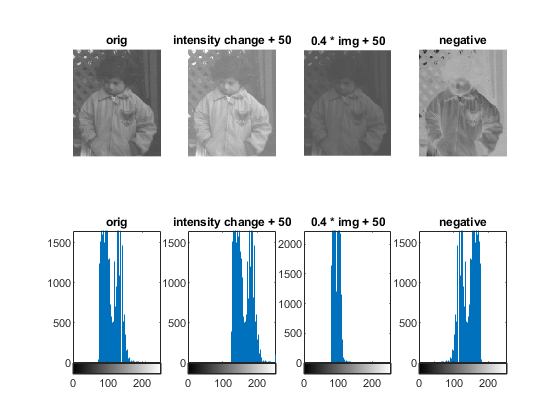

I = imread('pout.tif');
img_brightness_contrast = changeBrighnessAndContrast(I, 0.4, 50);
img_brightness = changeBrighnessAndContrast(I, 1, 50);
img_contrast = changeBrighnessAndContrast(I, 0.4, 0);
negative = changeBrighnessAndContrast(I, -1, 255);

figure
subplot(241); imshow(I); title("orig");
subplot(242); imshow(img_brightness); title("intensity change + 50");
subplot(243); imshow(img_brightness_contrast); title("0.4 * img + 50");
subplot(244); imshow(negative); title("negative");

subplot(245); imhist(I); title("orig");
subplot(246); imhist(img_brightness); title("intensity change + 50");
subplot(247); imhist(img_brightness_contrast); title("0.4 * img + 50");
subplot(248); imhist(negative); title("negative");

compare imadjust and our function:

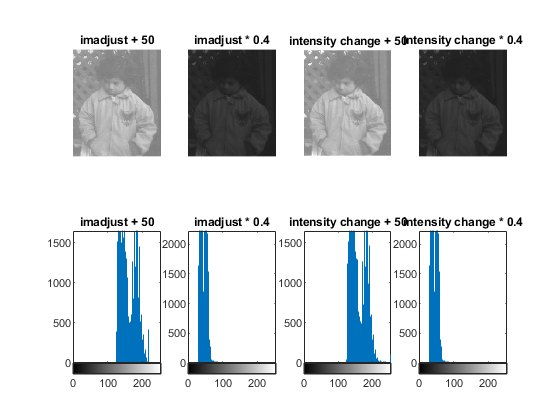

j = imadjust(I,[0.2941 0.6667],[0.49 0.8627]); % change brighness
j2 = imadjust(I,[0 1],[0 0.4]); % change * 0.4

figure
subplot(241); imshow(j); title("imadjust + 50");
subplot(242); imshow(j2); title("imadjust * 0.4");
subplot(243); imshow(img_brightness); title("intensity change + 50");
subplot(244); imshow(img_contrast); title("intensity change * 0.4");
subplot(245); imhist(j); title("imadjust + 50");
subplot(246); imhist(j2); title("imadjust * 0.4");
subplot(247); imhist(img_brightness); title("intensity change + 50");
subplot(248); imhist(img_contrast); title("intensity change * 0.4");

2.1.2

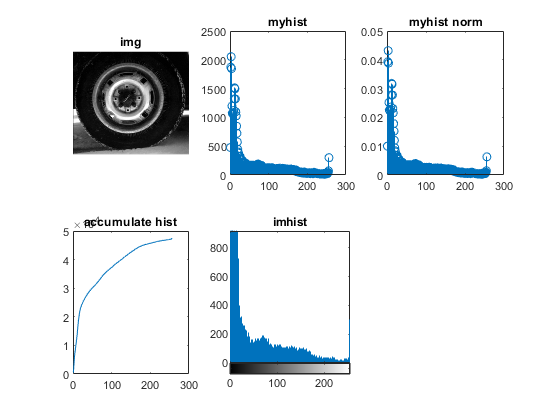

I = imread('tire.tif');
arrHist = myhist(I);
figure()
subplot(231); imshow(I); title("img");
subplot(232); stem(arrHist(2,:)); title("myhist");
subplot(233); stem(arrHist(3,:)); title("myhist norm");
subplot(234); plot(arrHist(4,:)); title("accumulate hist");
subplot(235); imhist(I); title("imhist");

2.3.1

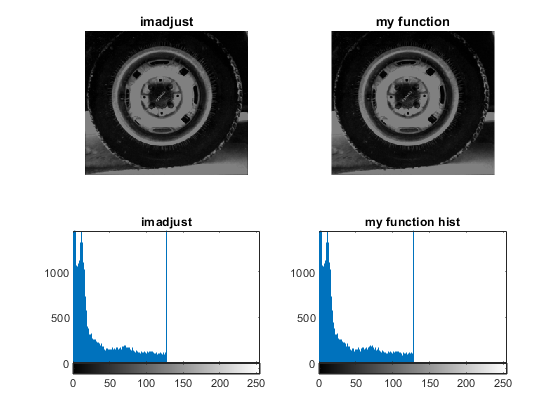

I = imread('tire.tif');
J = imadjust(I,[0 0.5],[0 0.5]);
J2 = imadjust_custom(I, 0, 0.5, 0, 0.5, 1);

figure
subplot(221); imshow(J); title("imadjust");
subplot(222); imshow(J2); title("my function");
subplot(223); imhist(J); title("imadjust");
subplot(224); imhist(J2); title("my function hist");

no difference between this and my own adjustment:

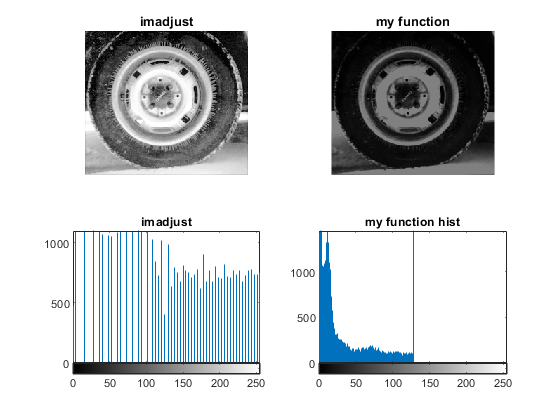

J = histeq(I);

figure
subplot(221); imshow(J); title("imadjust");
subplot(222); imshow(J2); title("my function");
subplot(223); imhist(J); title("imadjust");
subplot(224); imhist(J2); title("my function hist")

functions:

function arr = myhist(img)
    arr = zeros(4,255);
    arr(1,:) =  1:255;
    for i=0:255
        arr(2,i+1) = sum(sum(img == i));
    end
    hmin = min(arr(2,:));
    hmax = max(arr(2,:));
    %arr(3,:) = (arr(2,:) - hmin) ./ (hmax - hmin);    
    arr(3,:) =  arr(2,:) / sum(arr(2,:));
    arr(4,:) = cumsum(arr(2,:));
end


function res = imadjust_custom(I, low_in, high_in ,low_out ,high_out, gamma)
   res =  low_out + (high_out - low_out) .* ((I - low_in) / (high_in - low_in)) .^ gamma;
end 


function res = changeBrighnessAndContrast(img, c, b)
    I = double(img);
    I = c*I + b;
    res = uint8(I);
end